clear all; clc; close all;


L = 1 ;
T_base = eye(4) ;
q = [deg2rad(-90), deg2rad(-90), deg2rad(0), deg2rad(90)];
% Forward Kinematics 
FK = localFK(q,L) 

FK =     0.0000    1.0000         0   -2.0000
   -1.0000    0.0000         0   -2.0000
         0         0    1.0000         0
         0         0         0    1.0000


% Jacobian
Jacobian = Jacob(T_base, FK, q, L) 

Jacobian =     2.0000    1.0000    0.0000   -1.0000
   -2.0000   -3.0000   -2.0000   -1.0000
         0         0         0         0
         0         0         0         0
         0         0         0         0
    1.0000    1.0000    1.0000    1.0000


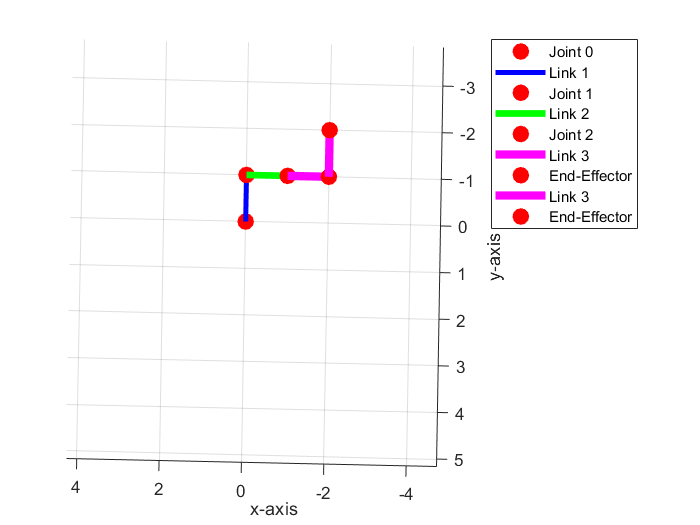

% RObot Visualization
figure
robot(L,q)
xlim([-4.74 4.26])
ylim([-3.83 5.17])
zlim([-3.50 5.50])
view([-178.85 90.00])

%%
% Jacobian Based Method
W = diag([0.1, 0.2, 0.5, 0.7])

W =     0.1000         0         0         0
         0    0.2000         0         0
         0         0    0.5000         0
         0         0         0    0.7000


J_hash = Jacob_Based(Jacobian, "pinv", W)

J_hash =     0.5000    0.5000    1.0000
   -0.1667   -0.6667   -1.0000
   -0.1667   -0.1667         0
   -0.1667    0.3333    1.0000


J_hash_W = Jacob_Based(Jacobian, "weighted pinv", W)

J_hash_W =     0.5000    0.5000    1.0000
   -0.1724   -0.7586   -1.1724
   -0.1552    0.0172    0.3448
   -0.1724    0.2414    0.8276


FK =    -1.0000   -0.0000         0   -2.0000
    0.0000   -1.0000         0    2.0000
         0         0    1.0000         0
         0         0         0    1.0000


Jacobian =    -2.0000   -1.0000   -0.0000   -1.0000
   -2.0000   -1.0000         0    1.0000
         0         0         0         0
         0         0         0         0
         0         0         0         0
    1.0000    1.0000    1.0000    1.0000


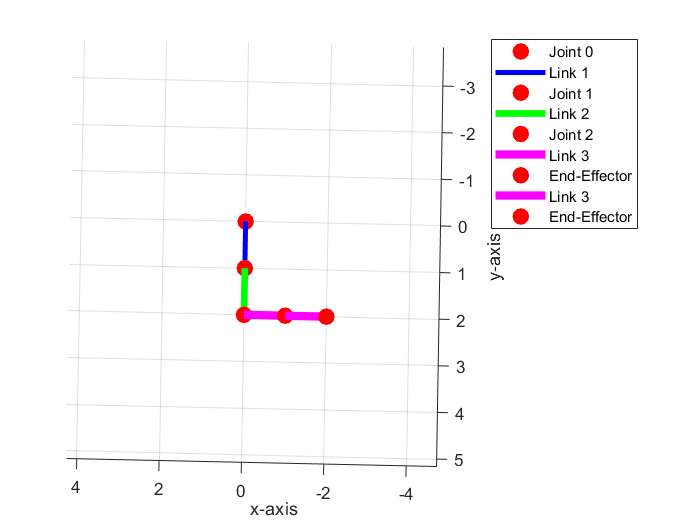

W =     0.1000         0         0         0
         0    0.2000         0         0
         0         0    0.5000         0
         0         0         0    0.7000


J =    -2.0000   -1.0000   -0.0000   -1.0000
   -2.0000   -1.0000         0    1.0000
    1.0000    1.0000    1.0000    1.0000


J_hash =    -0.3333   -0.1667   -0.1667
    0.1667   -0.1667    0.3333
    0.6667   -0.1667    0.8333
   -0.5000    0.5000    0.0000


J =    -2.0000   -1.0000   -0.0000   -1.0000
   -2.0000   -1.0000         0    1.0000
    1.0000    1.0000    1.0000    1.0000


J_hash_W =    -0.5000   -0.1429   -0.3571
    0.5000   -0.2143    0.7143
    0.5000   -0.1429    0.6429
   -0.5000    0.5000    0.0000



final_pos = FK(1:2,4); % [x,y]  position in x,y plane

final_ori = atan2(FK(2,1), FK(1,1)); % [phi] orientation around z
final = [final_pos', final_ori]

q = [deg2rad(0), deg2rad(0), deg2rad(0), deg2rad(0)]';
FK = localFK(q,L);
initial_pos = FK(1:2,4);
initial_ori = atan2(FK(2,1), FK(1,1));
initial = [initial_pos', initial_ori]

current = initial;
% step = (final - initial)/10 ;
i = 1;
while (sum(abs(final - current)) > 0.01)
    
    Task_step = (final - current)/10 ;
    new = current + Task_step;
    J_hash = Jacob_Based(Jacobian, "pinv", W);
    Joint_step = J_hash * Task_step';
    qs(1:4,i) = q + Joint_step;

% visualizing the Robot's Path
    clf
    robot(L,qs(:,i));
    xlim([-4.74 4.26])
    ylim([-3.83 5.17])
    zlim([-3.50 5.50])
    view([-178.85 90.00])    
    pause(0.01)
    
    q = qs(1:4,i);
    FK = localFK(q,L);
    Jacobian = Jacob(T_base, FK, q, L);
    current = [FK(1:2,4)', atan2(FK(2,1), FK(1,1))];
    i = i + 1;
    
    %%%
%     new = current + step;
% 
%     qs(1:4,i) = J_hash * new';
%     current = new;
%     i = i + 1;
    %%%
end

%%
% % visualizing the Robot's Path
% close all;
% figure
% for i = 1:10:length(qs)
%     clf
%     robot(L,qs(:,i));
%     xlim([-4.74 4.26])
%     ylim([-3.83 5.17])
%     zlim([-3.50 5.50])
%     view([-178.85 90.00])
%     pause(0.01)
% end
%%


